global pt1 pt06 pt03 pt01 pt003 
load("experimental_data.mat")

warning('off')

x0_ = [0.00264828798257004	
2.14787309889590	
29.4615907561718	
0.0643507608371836	
0.416871459858977	
61.3862383698715	
1.29851256252989];


MU  = x0_(1);
ALPHA = x0_(2);
KELAS = x0_(3);
MUVIS = x0_(4);
ALPHAVIS = x0_(5);
KVIS = x0_(6);
RTIME = x0_(7);
% 
x0=[MU, ALPHA, KELAS, MUVIS, ALPHAVIS, KVIS, RTIME];
global xsol
xsol = zeros(size(x0));
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1, 15);
ub = [];
nonlcon = [];
penalty = 1e10;
f1 = @loss_function_lsq_1EL_NR;
f2 = @constraint1EL;
loss_function_lsq_cstr = @(x) f1(x) + penalty * f2(x);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          8         4061.46                       4.3e+06
     1         16         1607.94        4.02862       1.89e+06      
     2         24         526.965             10       5.55e+05      
     3         32         194.637        3.02388       8.55e+04      
     4         40         194.637        1.37874       8.55e+04      
     5         48         191.769       0.344686       1.56e+04      
     6         56         187.363       0.483271       1.87e+04      
     7         64         187.363       0.689372       1.87e+04      
     8         72         187.363       0.172343       1.87e+04      
     9         80         187.282      0.0430857            943      
    10         88         187.166      0.0861715            223      
    11         96         187.115       0.172343           90.9      
    12        104         186.80

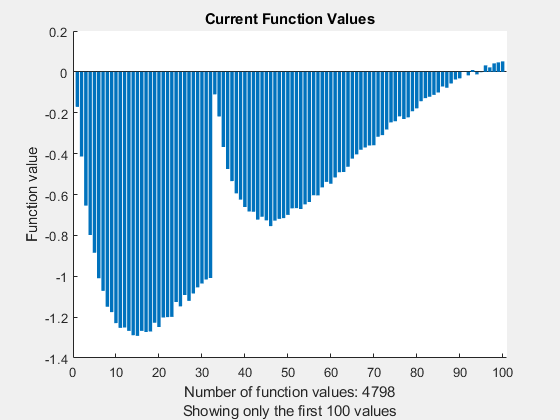


Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


x =     0.0032    2.0106   13.3308    0.0702    0.2715   22.6640    5.3390


fval = 186.7359

exitflag =    -0.1713
   -0.4139
   -0.6544
   -0.7982
   -0.8853
   -1.0096
   -1.0717
   -1.1495
   -1.1755
   -1.2291


output = 2

options = optimset('PlotFcns',@optimplotfval, 'MaxIter', 100, 'Display','iter');
[x,fval,exitflag,output] = lsqnonlin(loss_function_lsq_cstr, x0, lb, ub, options)

global DFGRD0 STRETCH_NEW STATEV DTIME ...
MU  ALPHA  KELAS  ...
MUVIS ALPHAVIS  KVIS ETADEV ETAVOL
optionsNR = optimoptions('fsolve','Display', 'none','FunctionTolerance', 1e-16, 'StepTolerance', 1e-16);

MU  = x(1);
ALPHA = x(2);
KELAS = x(3);
MUVIS = x(4);
ALPHAVIS = x(5);
KVIS = x(6);
RTIME = x(7);
ETADEV = RTIME * MUVIS * ALPHAVIS;
ETAVOL = RTIME * KVIS;



% loss for strain rate pt1
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt1 = size(pt1);
lenpt1 = lenpt1(1);
pt1sim = zeros(lenpt1, 2);
pt1sim(1,:) = [1, 0];
for datapoint = 2:lenpt1
    STRETCH_NEW = pt1(datapoint, 2);
    DTIME = pt1(datapoint, 4) - pt1(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA1EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL);

    DFGRD0 = DFGRD1;
    pt1sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt06
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt06 = size(pt06);
lenpt06 = lenpt06(1);
pt06sim = zeros(lenpt06, 2);
pt06sim(1,:) = [1, 0];
for datapoint = 2:lenpt06
    STRETCH_NEW = pt06(datapoint, 2);
    DTIME = pt06(datapoint, 4) - pt06(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA1EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL);

    DFGRD0 = DFGRD1;
    pt06sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt03
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt03 = size(pt03);
lenpt03 = lenpt03(1);
pt03sim = zeros(lenpt03, 2);
pt03sim(1,:) = [1, 0];
for datapoint = 2:lenpt03
    STRETCH_NEW = pt03(datapoint, 2);
    DTIME = pt03(datapoint, 4) - pt03(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA1EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL);

    DFGRD0 = DFGRD1;
    pt03sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt01
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt01 = size(pt01);
lenpt01 = lenpt01(1);
pt01sim = zeros(lenpt01, 2);
pt01sim(1,:) = [1, 0];
for datapoint = 2:lenpt01
    STRETCH_NEW = pt01(datapoint, 2);
    DTIME = pt01(datapoint, 4) - pt01(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA1EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL);

    DFGRD0 = DFGRD1;
    pt01sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end

% loss for strain rate pt003
DFGRD0 = eye(3);
DFGRD1 = eye(3);
STATEV = zeros(18,1);
STRESS = zeros(6,1);
DDSDDE = zeros(6,6);
FIRSTPIOLA = zeros(3,3);
STATEV(1) = 1.0;
STATEV(2) = 1.0;
STATEV(3) = 1.0;
STATEV(4) = 0.0;
STATEV(5) = 0.0;
STATEV(6) = 0.0;
STATEV(7) = 1.0;
STATEV(8) = 1.0;
STATEV(9) = 1.0;
STATEV(13) = 1.0;
STATEV(14) = 1.0;
STATEV(15) = 1.0;
DFGRD0(1,1) = 1.0;
DFGRD0(2,2) = 1.0;
DFGRD0(3,3) = 1.0;



lenpt003 = size(pt003);
lenpt003 = lenpt003(1);
pt003sim = zeros(lenpt003, 2);
pt003sim(1,:) = [1, 0];
for datapoint = 2:lenpt003
    STRETCH_NEW = pt003(datapoint, 2);
    DTIME = pt003(datapoint, 4) - pt003(datapoint-1, 4);

    % Solve for Stretch 22 and 33 such that First Piola22 and 33 = 0
    STRETCH_LAT = fsolve(@PIOLA1EL, STRETCH_NEW^(-0.5), optionsNR);
    
    DFGRD1(1,1) = STRETCH_NEW;
    DFGRD1(2,2) = STRETCH_LAT; % Stretch 22
    DFGRD1(3,3) = STRETCH_LAT; % Stretch 33
    [STATEV, STRESS, DDSDDE, FIRSTPIOLA, exitflag] = VISCOEL_OGDEN(DFGRD0, DFGRD1, STATEV, DTIME, ...
                                                         MU, ALPHA, KELAS, ...
                                                         MUVIS, ALPHAVIS, KVIS, ETADEV, ETAVOL);

    DFGRD0 = DFGRD1;
    pt003sim(datapoint,:) = [STRETCH_NEW, FIRSTPIOLA(1,1)*1000.0];
end





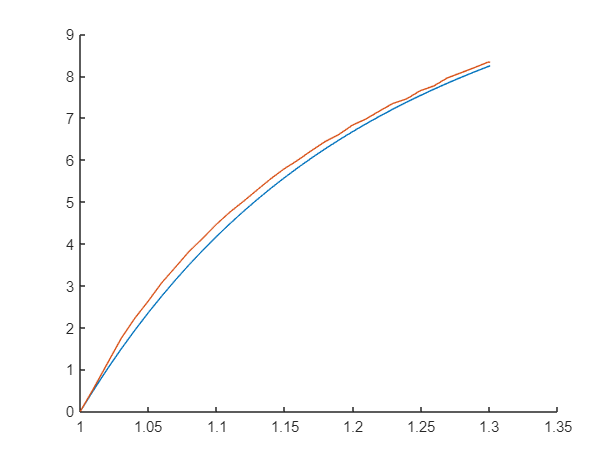

close all
hold on
plot(pt1sim(:,1), pt1sim(:,2));
plot(pt1(:,2), pt1(:,1));
hold off

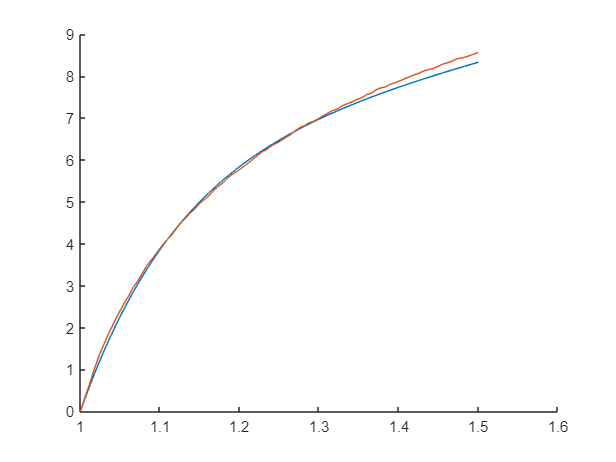

close all
hold on
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt06(:,2), pt06(:,1));
hold off

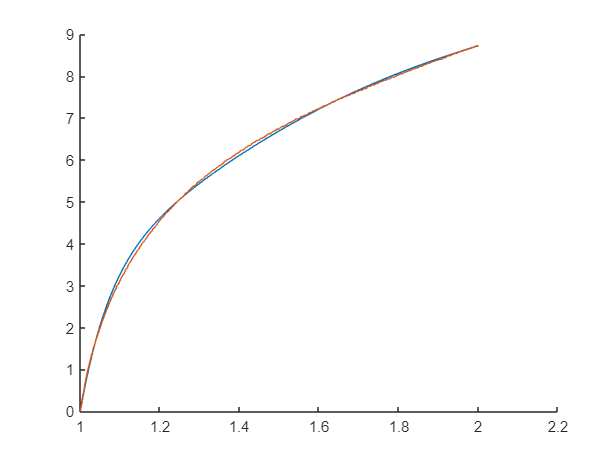

close all
hold on
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt03(:,2), pt03(:,1));
hold off

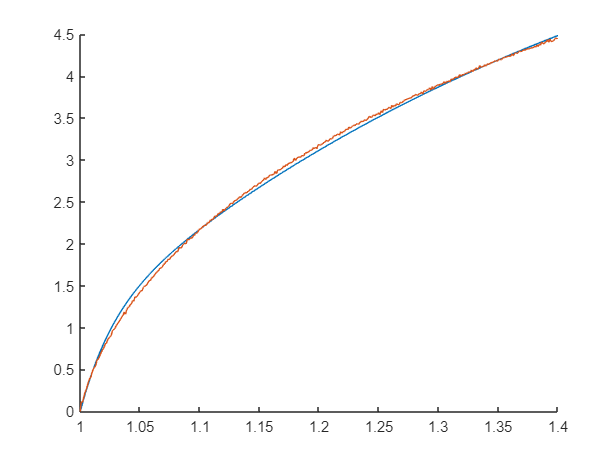

close all
hold on
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt01(:,2), pt01(:,1));
xlim([1, 1.4])
hold off

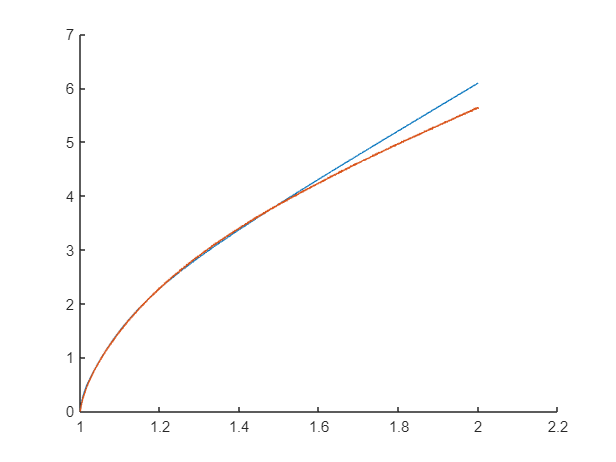

close all
hold on
plot(pt003sim(:,1), pt003sim(:,2));
plot(pt003(:,2), pt003(:,1));
hold off

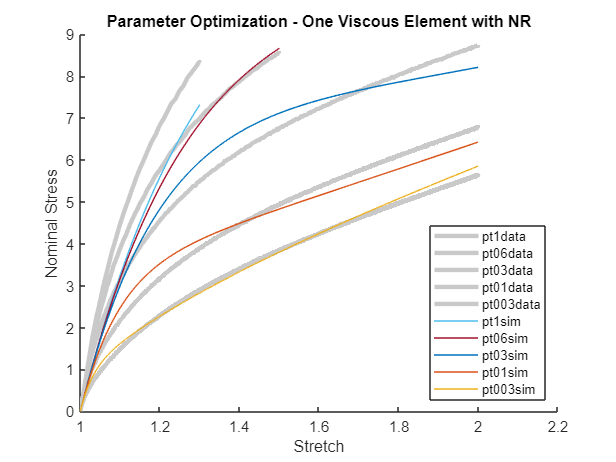

close all
hold on
plot(pt1(:,2), pt1(:,1),'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt06(:,2), pt06(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt03(:,2), pt03(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt01(:,2), pt01(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);
plot(pt003(:,2), pt003(:,1), 'Color', '#c9c9c9', 'LineWidth', 3);

plot(pt1sim(:,1), pt1sim(:,2));
plot(pt06sim(:,1), pt06sim(:,2));
plot(pt03sim(:,1), pt03sim(:,2));
plot(pt01sim(:,1), pt01sim(:,2));
plot(pt003sim(:,1), pt003sim(:,2));
legend('pt1data', 'pt06data', 'pt03data', 'pt01data', 'pt003data', 'pt1sim', 'pt06sim', 'pt03sim', 'pt01sim', 'pt003sim', 'Location', 'southeast')
xlabel('Stretch')
ylabel('Nominal Stress')
title('Parameter Optimization - One Viscous Element with NR')

hold off